# **WM9QE: Applied Statistics for Artificial Intelligence**

**Independent Learning Exercises (Solutions): Introduction to MATLAB Programming  **

In this section, you will practice writing MATLAB code for AI & Data Science examples using. Try to solve each problem by writing your own code below the description. Before attempting these exercises, make sure you have reviewed all sections of the MATLAB Programming seminar. 

**Useful links/references:**

- [Moodle Page: Week One | WM9QE:Applied Statistics for Artificial Intelligence](https://moodle.warwick.ac.uk/course/section.php?id=576666)

- [GitHub Repository](https://github.com/LeonardooAlves/WM9QE-ASAI/)

### Exercise 1: Thresholding Predictions (Binary Classification)

You are given a list of prediction probabilities from a binary classifier: **[0.95, 0.20, 0.65, 0.49, 0.85]**

A classification threshold of 0.5 should be applied: 

- If the probability is >= 0.5, classify it as Class 1 

- Otherwise, classify it as Class 0

**Task:** Write MATLAB code that loops through the probabilities and produces a vector of predicted class labels. Finally, display the predicted labels.

% >>> Write your code here <<<
clc; clear; clf;

pred_probs = [0.95, 0.20, 0.65, 0.49, 0.85];
threshold = 0.5;
pred_labels = [];  % start with empty vector

for p = pred_probs
    if p >= threshold
        pred_labels(end+1) = 1;   % assign Class 1
    else
        pred_labels(end+1) = 0;   % assign Class 0
    end
end

disp("Predicted labels:")

Predicted labels:


disp(pred_labels)

     1     0     1     0     1



### Exercise 2: Data Cleaning with IF

A set of sensor readings is recorded as: **[20, 21, 999, 19, -5, 22, 20]**

Not all values are valid. 

- A reasonable reading must be greater than 0 and less than 100 

- Values outside this range should be removed

**Task:** Write MATLAB code that uses a loop and an IF statement to remove the invalid values and create a cleaned dataset. Finally, display the cleaned sensor data.

% >>> Write your code here <<<
clc; clear; clf;

sensor_data = [20, 21, 999, 19, -5, 22, 20];
cleaned_data = [];

for s = sensor_data
    if s > 0 && s < 100
        cleaned_data(end+1) = s;   % keep only valid values
    end
end

disp("Cleaned sensor data:")

Cleaned sensor data:


disp(cleaned_data)

    20    21    19    22    20



### Exercise 3: Accuracy Calculation in AI

In a small classification task, you have the following labels:

- True labels: [1 0 1 0 1]

- Predicted labels:[1 0 0 0 1]

**Task:** Write MATLAB code to calculate the model's accuracy.

- Accuracy = (Number of correct predictions) / (Total predictions)

Use a loop to compare each pair of labels, count the number of correct matches, and compute accuracy as a percentage. Finally, display the accuracy.

% >>> Write your code here <<<
clc; clear; clf;

true_labels = [1 0 1 0 1];
pred_labels = [1 0 0 0 1];

correct = 0;
for i = 1:length(true_labels)
    if true_labels(i) == pred_labels(i)
        correct = correct + 1;   % increment if correct
    end
end

accuracy = correct / length(true_labels);
disp("Model Accuracy: " + accuracy*100 + "%")

Model Accuracy: 80%


### Exercise 4: Visualizing Random Student Scores

Description: You are a data analyst for a school. You have exam scores for 30 students in a class. You want to understand the distribution of scores and identify the highest and lowest scores.

**Instructions**: 

- Generate 30 random scores between 50 and 100. 

- Create a histogram to visualize the distribution. 

- Add title, x-axis and y-axis labels. 

- Include gridlines for clarity. 

- Comment in your code what the histogram tells you about the performance of the students.

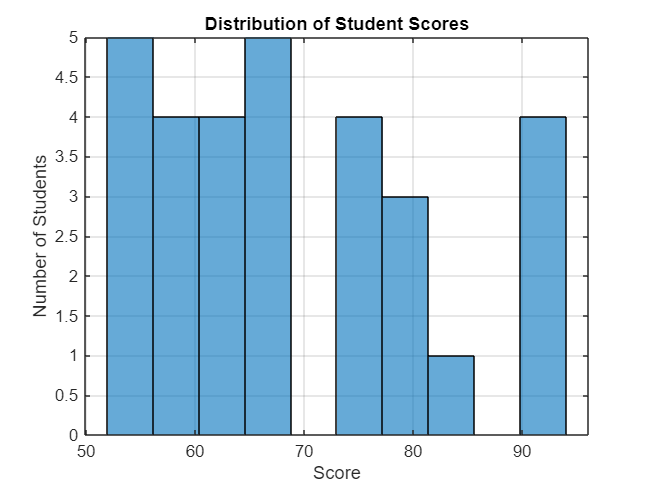

% >>> Write your code here <<<
clc; clear; clf;

scores = randi([50,100],1,30);  % Generate 30 random integer scores
figure;
histogram(scores, 10);  % 10 bins
title('Distribution of Student Scores');
xlabel('Score'); ylabel('Number of Students');
grid on;


% Comment: Most students scored between X and Y. There are no very low scores, indicating good overall performance.

### Exercise 5: Predicting Student Scores

You have predictions from a simple regression model for student test scores: 

- pred_scores = [78, 85, 92, 88, 95]; 

- exam_numbers = 1:5; 

**Task: **Plot a line chart of predicted scores, highlight the highest score, and add title, labels, and grid.

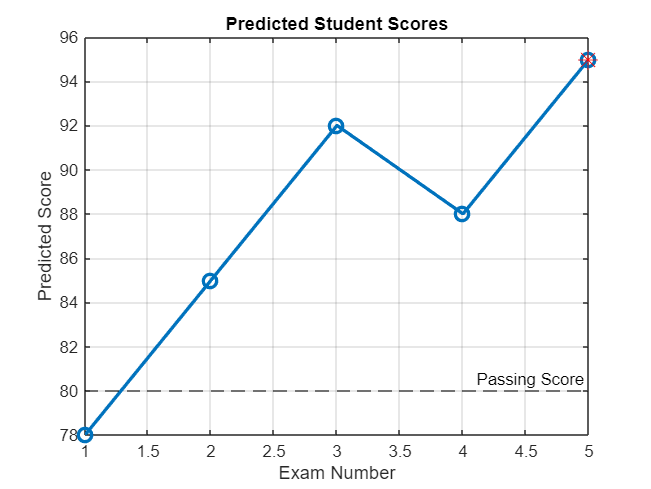

% >>> Write your code here <<<
clc; clear; clf;

pred_scores = [78, 85, 92, 88, 95];
exam_numbers = 1:5;

% Plot line chart
plot(exam_numbers, pred_scores, '-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on

% Highlight the highest score
[~, idx] = max(pred_scores); % index of highest score
plot(exam_numbers(idx), pred_scores(idx), 'r*', 'MarkerSize', 12);

% Add reference line for passing score
yline(80, '--k', 'Passing Score');

% Add labels, title, and grid
xlabel('Exam Number'); ylabel('Predicted Score');
title('Predicted Student Scores'); grid on
hold off

### Exercise 6: Sensor Data Distribution

Generate 50 temperature readings (normal distribution, mean=25°C, std=3°C) 

Plot histogram and highlight bins above 28°C in a different color.

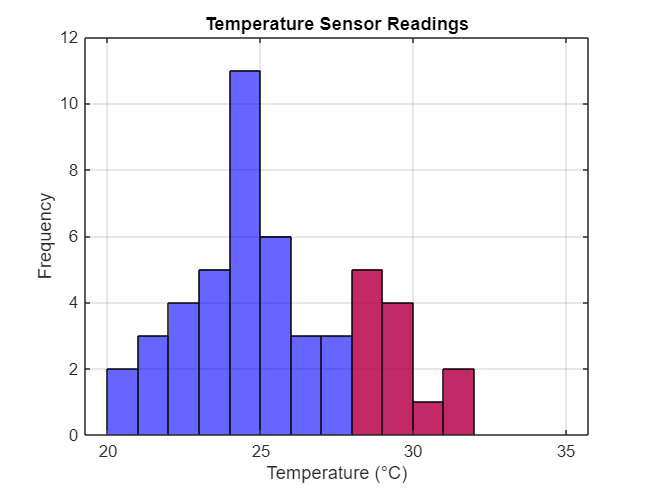

% >>> Write your code here <<<
clc; clear; clf;
%tip:
sensor_data = 25 + 3*randn(50,1); % generate random data
hist_edges = 20:1:35; % custom histogram bins

% Plot histogram for all data
histogram(sensor_data, hist_edges, 'FaceColor','b');
hold on

% Overlay histogram for values above 28°C
histogram(sensor_data(sensor_data>28), hist_edges, 'FaceColor','r');

xlabel('Temperature (°C)'); ylabel('Frequency');
title('Temperature Sensor Readings'); grid on
hold off

### Exercise 7: Comparing Algorithm Accuracy

Two classification algorithms report accuracies on 5 datasets: 

- algo1_acc = [0.85, 0.80, 0.78, 0.90, 0.88];

- algo2_acc = [0.82, 0.81, 0.76, 0.87, 0.89]; 

Plot a grouped bar chart with xticklabels.

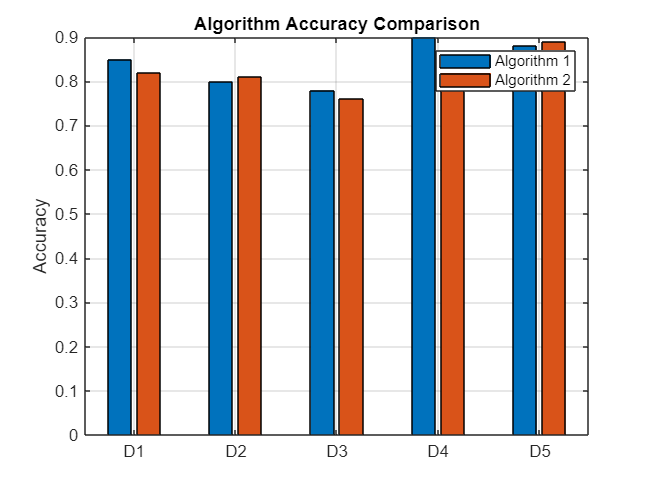

% >>> Write your code here <<<
clc; clear; clf;

algo1_acc = [0.85, 0.80, 0.78, 0.90, 0.88];
algo2_acc = [0.82, 0.81, 0.76, 0.87, 0.89];
dataset_labels = {'D1','D2','D3','D4','D5'};

bar([algo1_acc' algo2_acc']); % grouped bars
xticklabels(dataset_labels)
ylabel('Accuracy'); title('Algorithm Accuracy Comparison');
legend('Algorithm 1','Algorithm 2'); grid on

### Exercise 8: Feature Correlation Scatter Plot

You have two features: hours studied vs exam score 

- hours_studied = 1:10; 

- exam_score = [50,55,...,85]; 

Create scatter plot and fit a linear regression line.

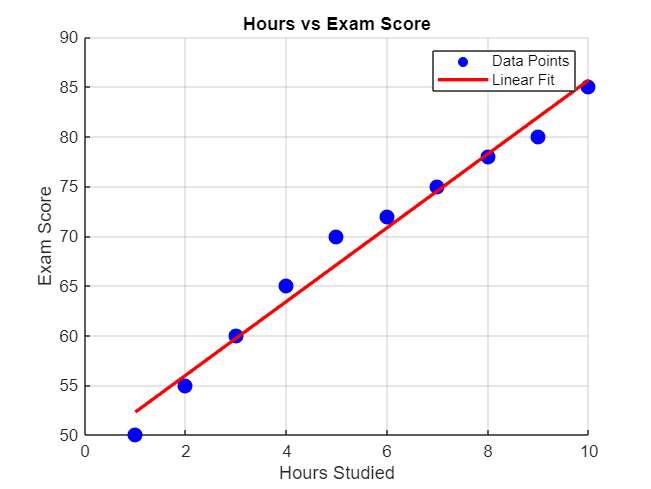

% >>> Write your code here <<<
clc; clear; clf;

hours_studied = 1:10;
exam_score = [50,55,60,65,70,72,75,78,80,85];

scatter(hours_studied, exam_score, 80, 'b','filled'); hold on

% Fit linear regression
p = polyfit(hours_studied, exam_score,1); % linear fit coefficients
y_fit = polyval(p,hours_studied); % compute fitted values

plot(hours_studied, y_fit, '-r','LineWidth',2); % plot fit
xlabel('Hours Studied'); ylabel('Exam Score');
title('Hours vs Exam Score'); grid on
legend('Data Points','Linear Fit'); hold off

### Exercise 9: Predicted vs Actual Values

Predicted and actual house prices: 

- predicted = [210,220,250,270,300]; 

- actual = [200,225,245,280,310]; 

Plot both lines on the same figure with legend and labels.

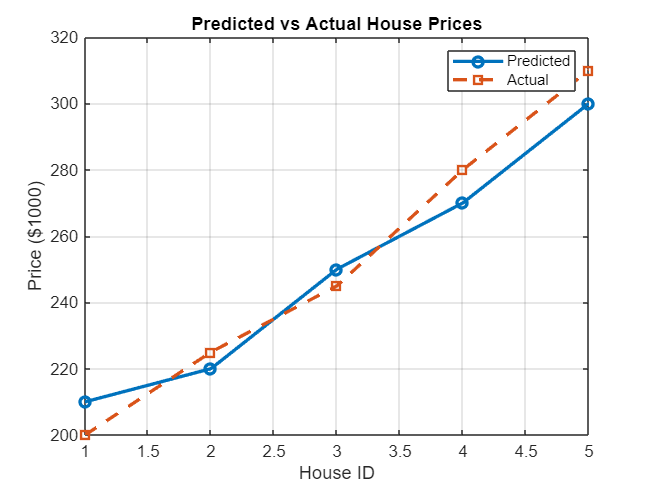

% >>> Write your code here <<<
clc; clear; clf;

predicted = [210,220,250,270,300];
actual = [200,225,245,280,310];
house_ids = 1:5;

plot(house_ids, predicted,'-o','LineWidth',2); hold on
plot(house_ids, actual,'--s','LineWidth',2);
xlabel('House ID'); ylabel('Price ($1000)');
title('Predicted vs Actual House Prices');
legend('Predicted','Actual'); grid on; hold off

### Exercise 10: Subplots for Distribution Analysis

- Feature1: normal distribution (mean=50,std=10) 

- Feature2: uniform distribution (min=40,max=70) 

Generate 100 points each, plot side-by-side subplots.

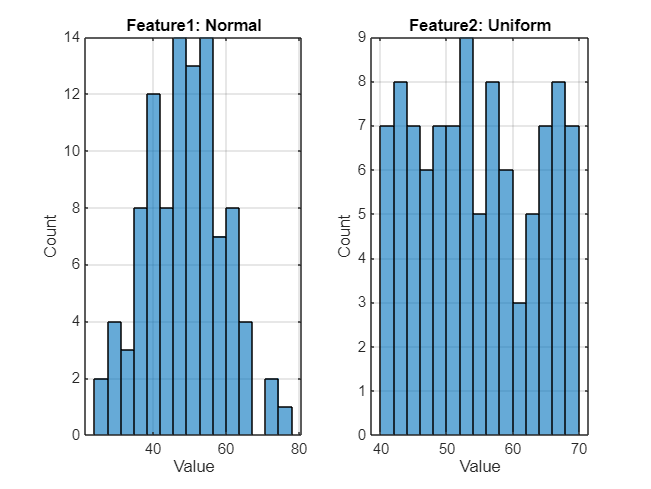

% >>> Write your code here <<<
clc; clear; clf;

feature1 = 50 + 10*randn(100,1);
feature2 = 40 + (70-40)*rand(100,1);

figure;
subplot(1,2,1);
histogram(feature1,15); title('Feature1: Normal'); xlabel('Value'); ylabel('Count'); grid on

subplot(1,2,2);
histogram(feature2,15); title('Feature2: Uniform'); xlabel('Value'); ylabel('Count'); grid on

### Exercise 11: Multi-class Classification Predictions

Predicted probabilities for 3 classes across 5 samples: 

- pred_probs = [0.7 0.2 0.1; 0.3 0.4 0.3; 0.2 0.2 0.6; 0.8 0.1 0.1; 0.1 0.1 0.8]; 

Plot grouped bar chart for each sample.

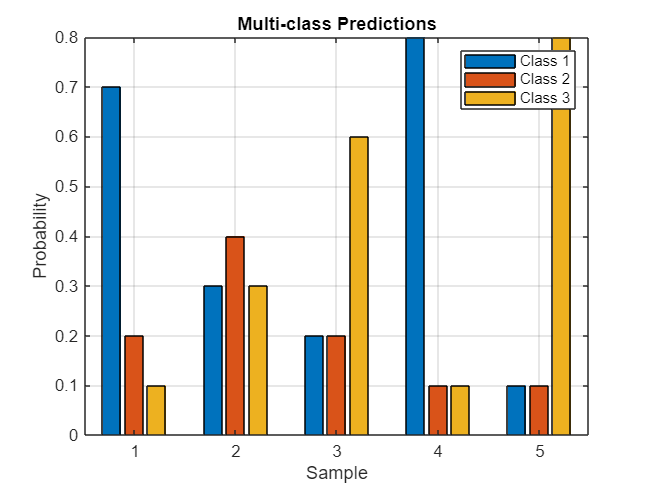

% >>> Write your code here <<<
clc; clear; clf;

pred_probs = [0.7 0.2 0.1; 0.3 0.4 0.3; 0.2 0.2 0.6; 0.8 0.1 0.1; 0.1 0.1 0.8];
bar(pred_probs); 
xticks(1:5); xlabel('Sample'); ylabel('Probability');
legend('Class 1','Class 2','Class 3'); 
title('Multi-class Predictions'); grid on

### Exercise 12: Comparing Daily Returns of Two Stocks

Description: You are analyzing daily returns of two stocks over 100 days to compare volatility. This is useful in finance to visualize risk.

Instructions: 

- Generate 100 random daily returns for Stock A (mean 0.001, std 0.02) and Stock B (mean 0.0005, std 0.03). 

- Create a grouped bar plot to compare the daily returns of both stocks. 

- Add xticklabels for selected days (e.g., every 10 days). 

- Add a legend to distinguish the two stocks. 

- Comment on which stock seems more volatile and why.

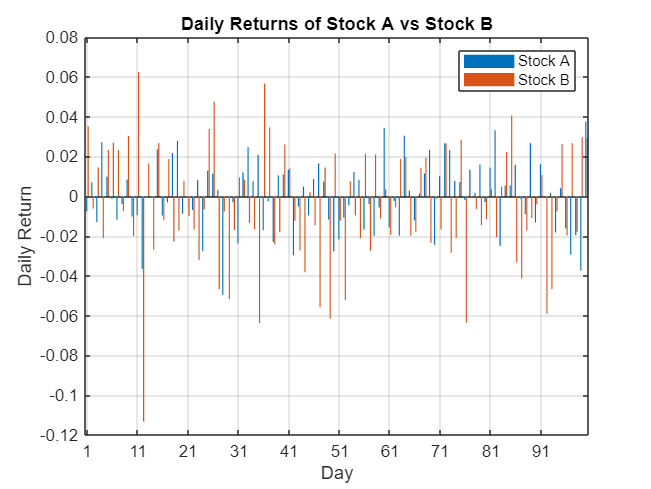

% >>> Write your code here <<<
clc; clear; clf;

days = 1:100;
stockA = 0.001 + 0.02*randn(1,100);
stockB = 0.0005 + 0.03*randn(1,100);

figure;
bar([stockA' stockB']);  % Grouped bar plot
xticks(1:10:100);
xticklabels(1:10:100);
xlabel('Day'); ylabel('Daily Return'); title('Daily Returns of Stock A vs Stock B');
legend('Stock A','Stock B');
grid on;


% Comment: Stock B shows larger variation, indicating higher volatility.
%}

### Exercise 13: Sensor Data Cleaning and Box Plot

Description: You have collected sensor measurements from a device. Some readings are invalid or extreme due to sensor errors. Use a box plot to detect and handle these outliers.

Instructions: 

- Create a vector with 20 sensor readings, including some extreme values like -5 or 200.

- Plot a box plot to visualize the distribution and identify outliers.

- Remove readings that are outside the normal range (e.g., 0–150). 

- Plot a new box plot for the cleaned data. 

- Comment on how cleaning the data changed the distribution.

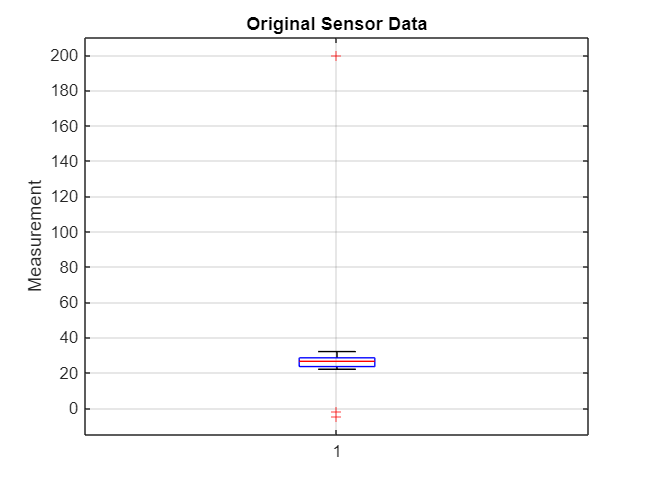

% >>> Write your code here <<<
clc; clear; clf;

sensor_data = [23, 25, -5, 27, 200, 30, 22, 26, 28, 29, 24, 31, 27, -2, 23, 26, 32, 25, 27, 28];
figure;
boxplot(sensor_data);
title('Original Sensor Data');
ylabel('Measurement');
grid on;

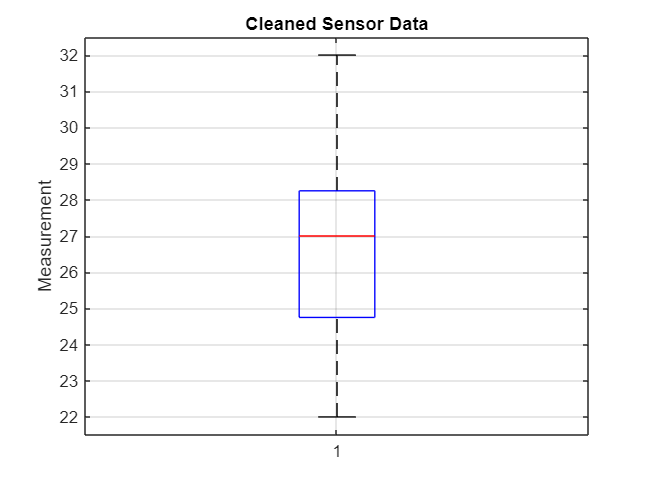


% Remove outliers
cleaned_data = sensor_data(sensor_data >= 0 & sensor_data <= 150);
figure;
boxplot(cleaned_data);
title('Cleaned Sensor Data');
ylabel('Measurement');
grid on;


% Comment: Outliers have been removed, distribution is now more representative of normal readings.
%}

### Exercise 14: AI Model Prediction Error Analysis

Description: You have errors from three different AI models predicting house prices. You want to compare the performance of the models.

Instructions: 

- Create three vectors, each containing 10 prediction errors (positive and negative values) for Model 1, Model 2, and Model 3. 

- Combine the data and create a grouped box plot to compare models. 

- Add title, axis labels, and a legend. 

- Identify which model has the smallest median error and the least variation. 

- Comment on which model you would choose and why, based on the plot.

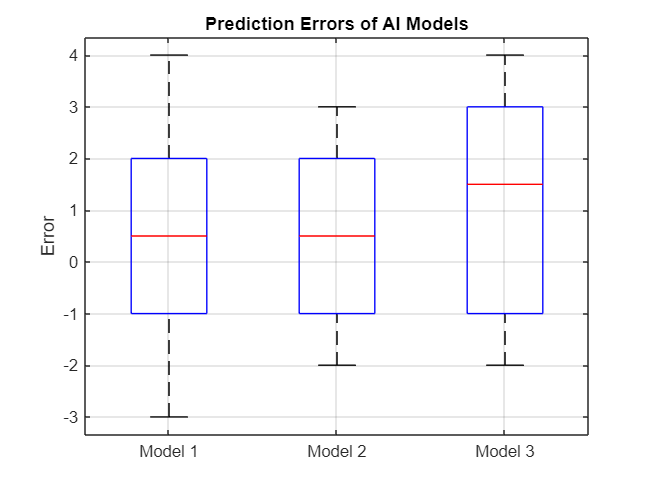

% >>> Write your code here <<<
clc; clear; clf;

model1 = [2, -1, 3, 0, -2, 1, 4, -3, 2, 0];
model2 = [1, -2, 2, -1, 3, -1, 2, -2, 1, 0];
model3 = [3, 2, -1, 4, -2, 3, 2, 1, 0, -1];

errors = [model1' model2' model3'];
figure;
boxplot(errors,'Labels',{'Model 1','Model 2','Model 3'});
title('Prediction Errors of AI Models');
ylabel('Error');
grid on;


% Comment: Model 2 has the smallest median and less spread, so it is the preferred model.
%}

### Exercise 15: Finance - Stock Returns

Task: Simulate daily returns of a stock using normal distribution.

- Generate 252 daily returns (1 year) with mean 0.1% and std 2%.

- Plot histogram of returns.

- Compute cumulative wealth over the year.

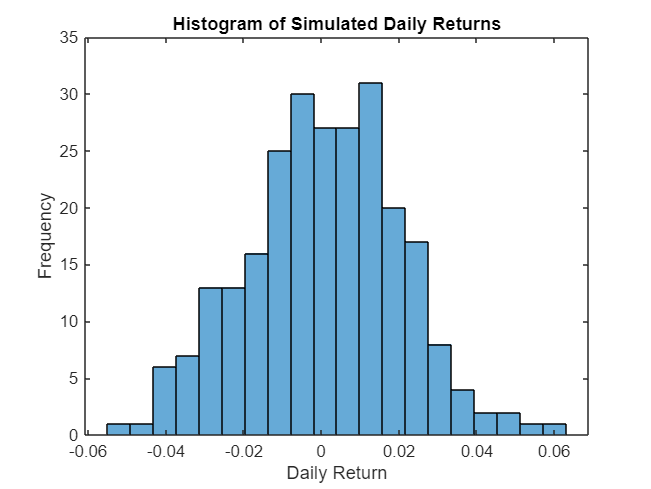

% >>> Write your code here <<<
clc; clear; clf;
% Tip:
n_days = 252;
daily_returns = normrnd(0.001, 0.02, [n_days,1]); 

% Histogram
figure;
histogram(daily_returns,20);
xlabel('Daily Return'); ylabel('Frequency');
title('Histogram of Simulated Daily Returns');

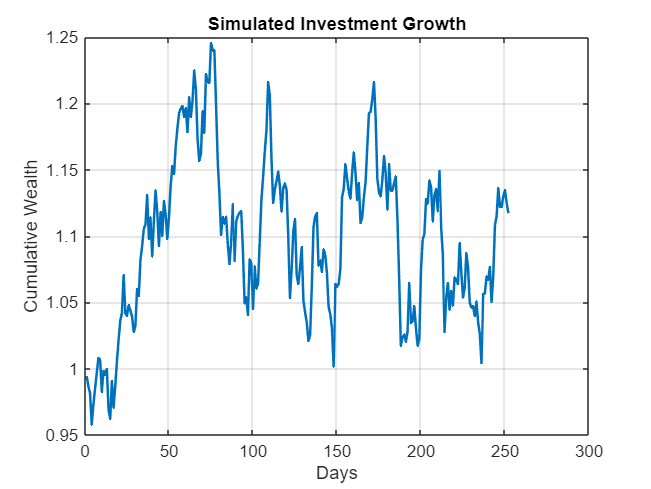


% Cumulative wealth
wealth = cumprod(1+daily_returns);
figure;
plot(wealth,'LineWidth',1.5);
xlabel('Days'); ylabel('Cumulative Wealth');
title('Simulated Investment Growth');
grid on;


% --- Solution interpretation:
final_growth = wealth(end);
fprintf('Final wealth multiplier over 1 year: %.2f\n', final_growth);

Final wealth multiplier over 1 year: 1.12


fprintf('Mean daily return: %.4f (%.2f%%)\n', mean(daily_returns), mean(daily_returns)*100);

Mean daily return: 0.0006 (0.06%)


fprintf('Volatility (std of daily returns): %.4f (%.2f%%)\n\n', std(daily_returns), std(daily_returns)*100);

Volatility (std of daily returns): 0.0199 (1.99%)



Try this:

- Change the mean return to 0.0005 (0.05% daily) and re-run. How does final wealth change?

- Simulate for 5 years (252*5 days). Plot again. What patterns do you see?

- Compare two stocks: one with high return but high risk, another safer.

### Exercise 16: Healthcare - Patient Vital Signs

Task: Analyze patient heart rate data.

- Generate synthetic heart rate values for 100 patients (mean=75, std=10).

- Plot histogram and compute % of patients with HR > 90.

- Create a table showing mean, min, max.

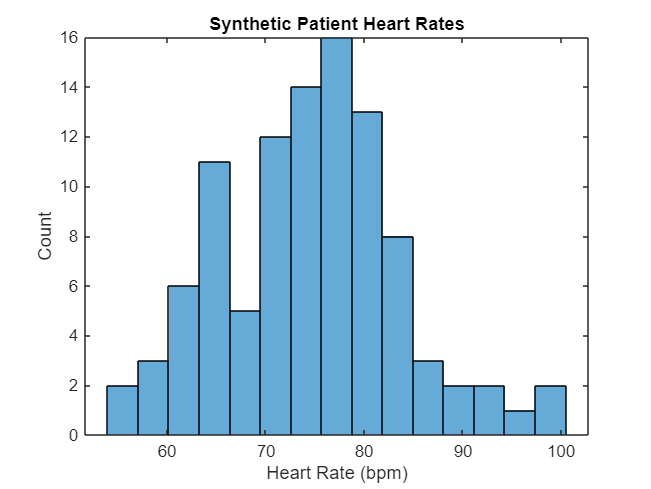

% >>> Write your code here <<<
clc; clear; clf;

hr = normrnd(75,10,[100,1]);

figure; histogram(hr,15);
xlabel('Heart Rate (bpm)'); ylabel('Count');
title('Synthetic Patient Heart Rates');


% Percentage with HR > 90
pct_high = mean(hr > 90)*100;

% Summary table
hrTable = table(mean(hr), min(hr), max(hr), ...
    'VariableNames', {'MeanHR','MinHR','MaxHR'});

% --- Solution interpretation:
disp(hrTable)

    MeanHR    MinHR     MaxHR 
    ______    ______    ______

    74.736    55.079    99.911



fprintf('Percentage of patients with HR > 90 bpm: %.1f%%\n\n', pct_high);

Percentage of patients with HR > 90 bpm: 6.0%



### Exercise 17*: Engineering - Sensor Reliability

Task: Failure counts from sensors follow a Poisson distribution.

- Simulate 200 sensors, failure rate λ=1.5 per year.

- Compare observed vs expected distribution with grouped bar chart.

- you can come back to this exercise once we reviewed the distribution, else you can use MATLAB help to generate Poisson distribution (`poissrnd`)

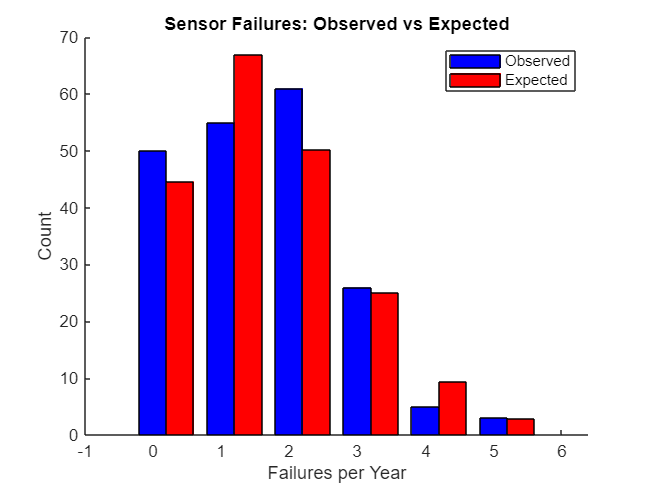

% >>> Write your code here <<<
clc; clear; clf;
% Tip:
failures = poissrnd(1.5,[200,1]);

% Observed counts (0–5 failures)
obs_counts = histcounts(failures,0:6);
exp_counts = poisspdf(0:5,1.5)*200;

figure; hold on;
bar(0:5, obs_counts, 0.4,'b');
bar((0:5)+0.4, exp_counts, 0.4,'r');
hold off;
xlabel('Failures per Year'); ylabel('Count');
title('Sensor Failures: Observed vs Expected');
legend('Observed','Expected');


% --- Solution interpretation:
compTable = table((0:5)', obs_counts', round(exp_counts'), ...
    'VariableNames', {'Failures','Observed','Expected'});
disp(compTable)

    Failures    Observed    Expected
    ________    ________    ________

       0           50          45   
       1           55          67   
       2           61          50   
       3           26          25   
       4            5           9   
       5            3           3   



fprintf('Total Observed: %d, Total Expected: %d\n\n', sum(obs_counts), round(sum(exp_counts)));

Total Observed: 200, Total Expected: 199

